# Chapter 6, Section 4 (Part 3)

In this activity, we will show why it is important that we have an orthogonal basis for the subspace $W$ on which we wish to do an orthogonal projection of a vector $\textbf v$. Let's begin with an example. 

# Example #1

In this example, we will show that if we don't have an orthogonal basis, the orthogonal projection method will not work. Let


$$\textbf v_1=\pmatrix{2\cr 0\cr 0},\qquad\textbf v_2=\pmatrix{1\cr 2\cr 0},\qquad\text{and}\qquad\textbf v=\pmatrix{3\cr 2\cr 2}$$


If $W=\text{span}\{\textbf v_1,\ \textbf v_2\}$, then $W$ is a plane, having the following equation:


$$\pmatrix{x\cr y\cr z}=s\pmatrix{2\cr 0\cr 0}+t\pmatrix{1\cr 2\cr 0}=\pmatrix{2s+t\cr 2t\cr 0}$$


Now, let's sketch the plane and add the vectors $\textbf v_1$, $\textbf v_2$, and $\textbf v$.

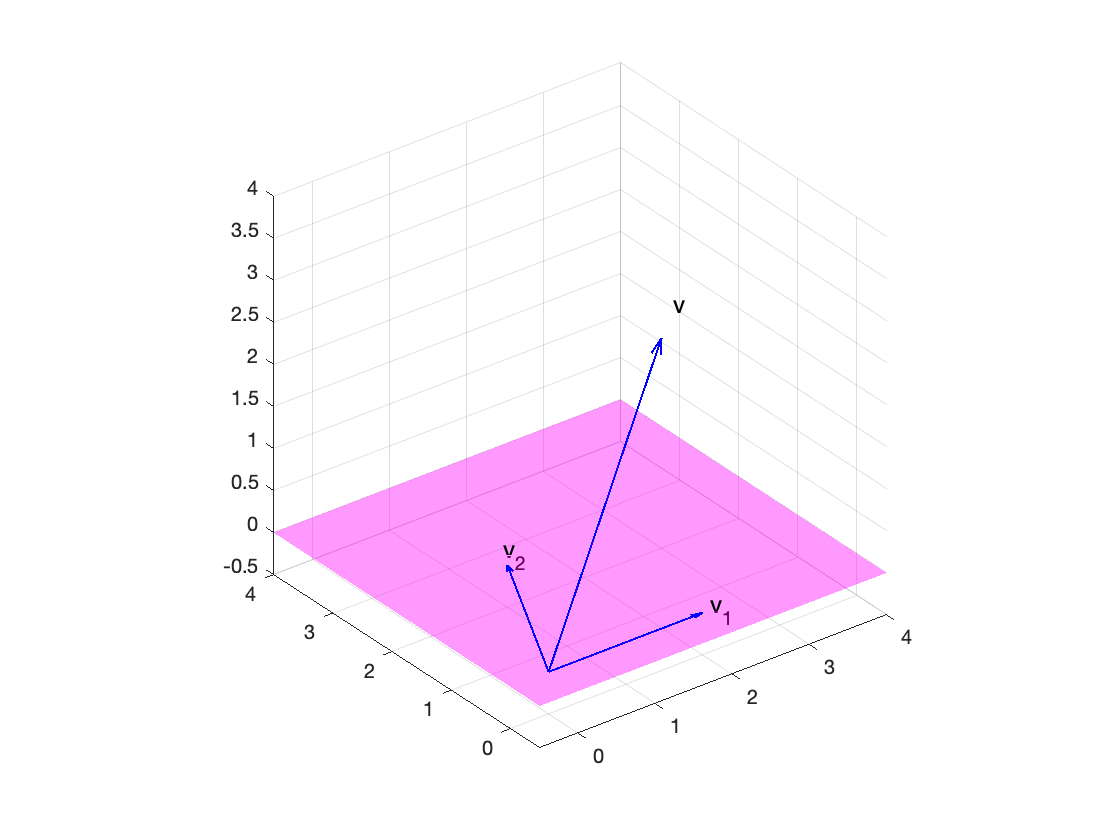

figure
hold on
s=linspace(-4,4,20);
t=linspace(-4,4,20);
[S,T]=meshgrid(s,t);
X=2*S+T;
Y=2*T;
Z=zeros(size(T));
surf(X,Y,Z,'FaceColor','m','FaceAlpha',0.4,'EdgeColor','none')
quiver3(0,0,0,2,0,0,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,1,2,0,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,3,2,2,0,'LineWidth',1,'Color','b')
axis equal
axis([-0.5,4,-0.5,4,-0.5,4])
grid on
text(2.1,0,0,'v_1','FontSize',12)
text(1.1,2.2,0,'v_2','FontSize',12)
text(3.3,2.2,2.2,'v','FontSize',12)
view(3)

Note that the vectors $\textbf v_1$ and $\textbf v_2$ do not appear to be orthogonal. We can check this with Matlab.

v1=[2;0;0]; v2=[1;2;0];
dot(v1,v2)

ans = 2

The dot product is not zero, so they are not orthogonal. Now, let's see what happens if we proceed with the orthogonal projection formula. Let's first compute the projections of the vector $\textbf v$ onto the vectors $\textbf v_1$ and $\textbf v_2$.

$\begin{array}{rcl}
\textbf{proj}_{\textbf v_1}\textbf v&=&\frac{\textbf v\cdot\textbf v_1}{\textbf v_1\cdot\textbf v_1}\textbf v_1\\
&=&\frac{(3,2,2)\cdot(2,0,0)}{2,0,0)\cdot(2,0,0)}\pmatrix{2\cr 0\cr 0}\\
&=&\frac{6}{4}\pmatrix{2\cr 0\cr 0}\\
&=&\pmatrix{3\cr 0\cr 0}
\end{array}$          and          $\begin{array}{rcl}
\textbf{proj}_{\textbf v_2}\textbf v&=&\frac{\textbf v\cdot\textbf v_2}{\textbf v_2\cdot\textbf v_2}\textbf v_2\\
&=&\frac{(3,2,2)\cdot(1,2,0)}{(1,2,0)\cdot(1,2,0)}\pmatrix{1\cr 2\cr 0}\\
&=&\frac{7}{5}\pmatrix{1\cr 2\cr 0}\\
&=&\pmatrix{7/5\cr 14/5\cr 0}
\end{array}$

We can check these with Matlab.

v=[3;2;2];proj1=dot(v,v1)/dot(v1,v1)*v1

proj1 =      3
     0
     0


proj2=dot(sym(v),v2)/dot(v2,v2)*v2

$$proj2 = \left(\begin{array}{c} \frac{7}{5}\\ \frac{14}{5}\\ 0 \end{array}\right)$$

Same answers. Now, let's add these projections to our image.

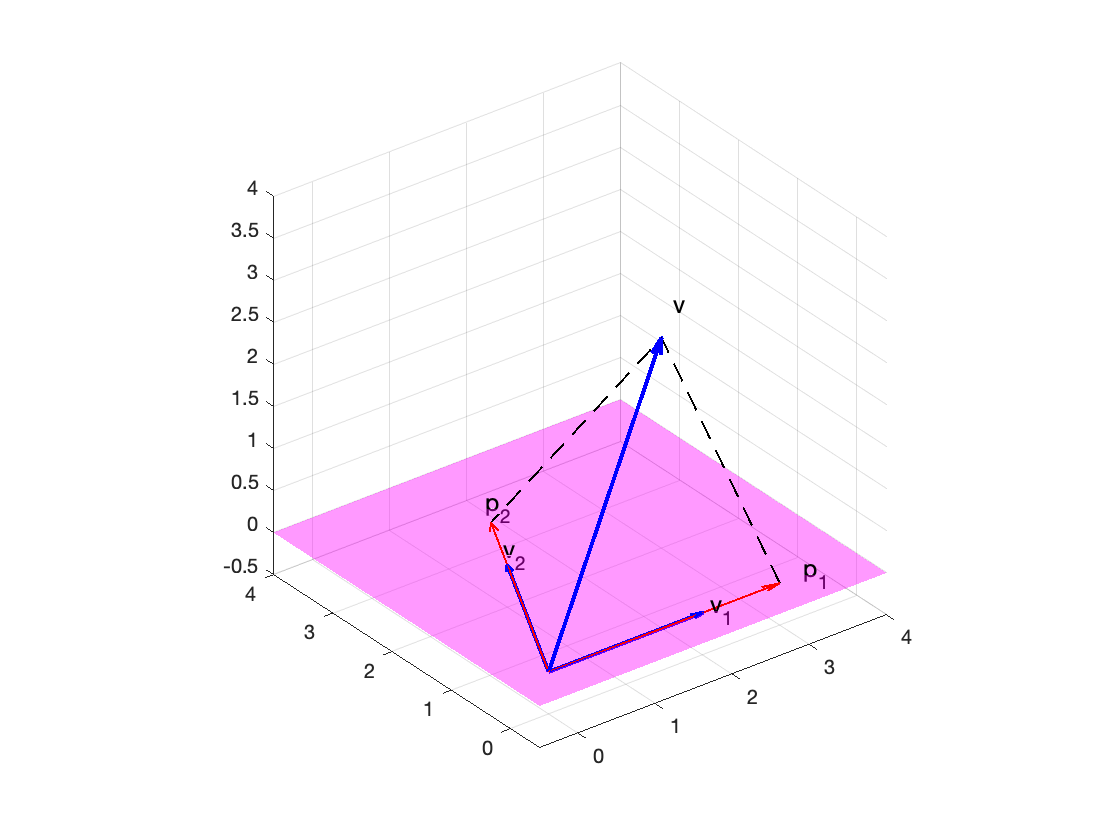

figure
hold on
s=linspace(-4,4,20);
t=linspace(-4,4,20);
[S,T]=meshgrid(s,t);
X=2*S+T;
Y=2*T;
Z=zeros(size(T));
surf(X,Y,Z,'FaceColor','m','FaceAlpha',0.4,'EdgeColor','none')
quiver3(0,0,0,2,0,0,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,1,2,0,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,3,2,2,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,3,0,0,0,'LineWidth',1,'Color','r')
quiver3(0,0,0,7/5,14/5,0,0,'LineWidth',1,'Color','r')
line([3,3,7/5],[0,2,14/5],[0,2,0],'LineWidth',1,'LineStyle','--','Color','k')
axis equal
axis([-0.5,4,-0.5,4,-0.5,4])
grid on
text(2.1,0,0,'v_1','FontSize',12)
text(1.1,2.2,0,'v_2','FontSize',12)
text(3.3,2.2,2.2,'v','FontSize',12)
text(3.3,0,0,'p_1','FontSize',12)
text(1.54,3.08,0,'p_2','FontSize',12)
view(3)

Next,


$$\textbf w=\text{proj}_{\textbf v_1}\textbf v+\text{proj}_{\textbf v_2}\textbf v=\pmatrix{3\cr 0\cr 0}+\pmatrix{7/5\cr 14/5\cr 0}=\pmatrix{22/5\cr 14/5\cr 0}$$


We can check this with Matlab.

w=dot(sym(v),v1)/dot(v1,v1)*v1+dot(v,v2)/dot(v2,v2)*v2

$$w = \left(\begin{array}{c} \frac{22}{5}\\ \frac{14}{5}\\ 0 \end{array}\right)$$

Next,


$$\textbf u=\textbf v-\textbf w=\pmatrix{3\cr 2\cr 2}-\pmatrix{22/5\cr 14/5\cr 0}=\pmatrix{-7/5\cr -4/5\cr 2}$$


And we can check this with Matlab.

u=v-w

$$u = \left(\begin{array}{c} -\frac{7}{5}\\ -\frac{4}{5}\\ 2 \end{array}\right)$$

Now, let's add these vectors to our image.

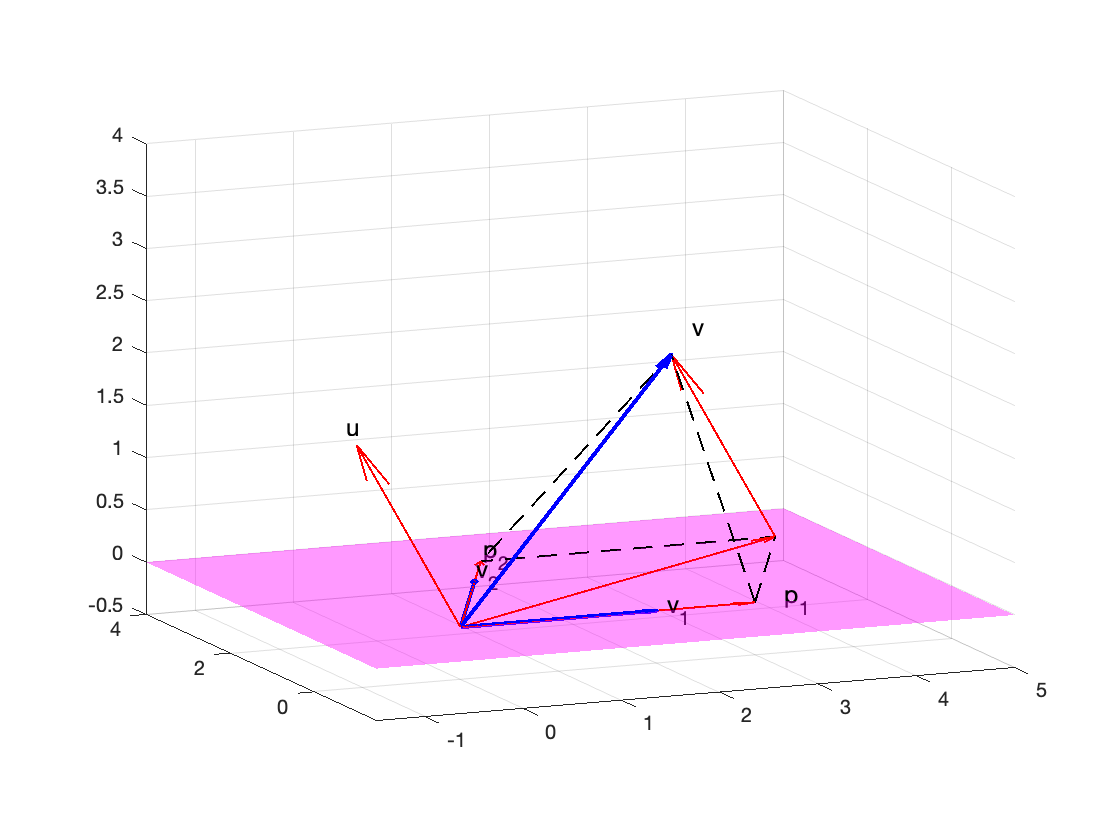

figure
hold on
s=linspace(-4,4,20);
t=linspace(-4,4,20);
[S,T]=meshgrid(s,t);
X=2*S+T;
Y=2*T;
Z=zeros(size(T));
surf(X,Y,Z,'FaceColor','m','FaceAlpha',0.4,'EdgeColor','none')
quiver3(0,0,0,2,0,0,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,1,2,0,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,3,2,2,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,3,0,0,0,'LineWidth',1,'Color','r')
quiver3(0,0,0,7/5,14/5,0,0,'LineWidth',1,'Color','r')
quiver3(0,0,0,22/5,14/5,0,0,'LineWidth',1,'Color','r')
quiver3(0,0,0,-7/5,-4/5,2,0,'LineWidth',1,'Color','r','MaxHeadSize',0.8)
quiver3(22/5,14/5,0,-7/5,-4/5,2,0,'LineWidth',1,'Color','r','MaxHeadSize',0.8)
line([3,3,7/5],[0,2,14/5],[0,2,0],'LineWidth',1,'LineStyle','--','Color','k')
line([3,22/5,7/5],[0,14/5,14/5],[0,0,0],'LineWidth',1,'LineStyle','--','Color','k')
axis equal
axis([-1.5,5,-1.5,4,-0.5,4])
grid on
text(2.1,0,0,'v_1','FontSize',12)
text(1.1,2.2,0,'v_2','FontSize',12)
text(3.3,2.2,2.2,'v','FontSize',12)
text(3.3,0,0,'p_1','FontSize',12)
text(1.54,3.08,0,'p_2','FontSize',12)
text(-1.54,-0.88,2.2,'u','FontSize',12)
view([-23.09 11.38])

This image gives clear evidence that this is not an orthogonal projection. The supposedly orthogonal component $\textbf u$ is **not** orthogonal to the plane. We can also check this by taking the dot product of the vector $\textbf v$ with each of the basis elements in the plane, namely, $\textbf v_1$ and $\textbf v_2$.

dot(u,v1)

$$ans = -\frac{14}{5}$$

dot(u,v2)

$$ans = -3$$

In order for $\textbf u$ to be the orthogonal component, it must be orthogonal to each basis vector, but it isn't.

**Important Observation: ** Now, what did we do wrong? The answer is, we didn't use an orthogonal basis for the plane $W=\text{span}\{\textbf v_1,\ \textbf v_2\}$. Now, we will fix this mistake in our next example.

# Example #2

Let


$$\textbf v_1=\pmatrix{2\cr 0\cr 0},\qquad\textbf v_2=\pmatrix{1\cr 2\cr 0},\qquad\text{and}\qquad\textbf v=\pmatrix{3\cr 2\cr 2}$$


Find the orthogonal projection of $\textbf v$ onto $W=\text{span}\{\textbf v_1,\ \textbf v_2\}$. 

**Solution:** The mistake we made in Example #1 is the fact that we did not start with an orthogonal basis for $W=\text{span}\{\textbf v_1,\ \textbf v_2\}$. This time we will use the Gram-Schmidt process to find an orthogonal basis for $W=\text{span}\{\textbf v_1,\ \textbf v_2\}$. Let


$$\textbf w_1=\textbf v_1=\pmatrix{2\cr 0\cr 0}$$


Next,


$$\begin{array}{rcl}
\textbf w_2&=&\textbf v_2-\text{proj}_{\textbf w_1}\textbf v_2\\
\textbf w_2&=&\textbf v_2-\frac{\textbf v_2\cdot\textbf w_1}{\textbf w_1\cdot\textbf w_1}\textbf w_1\\
\textbf w_2&=&\pmatrix{1\cr 2\cr 0}-\frac{2}{4}\pmatrix{2\cr 0\cr 0}\\
\textbf w_2&=&\pmatrix{0\cr 2\cr 0}
\end{array}$$


We can check our work with Matlab.

v1=[2;0;0];v2=[1;2;0];v=[3;2;2];
w1=v1

w1 =      2
     0
     0


w2=v2-dot(v2,w1)/dot(w1,w1)*w1

w2 =      0
     2
     0


And,

dot(w1,w2)

ans = 0

so they are orthogonal. Therefore, our orthogonal basis for $W=\text{span}\{\textbf v_1,\ \textbf v_2\}$ is 


$$B_W=\{\textbf w_1,\ \textbf w_2\}=\left\{\pmatrix{2\cr 0\cr 0},\ \pmatrix{0\cr 2\cr 0}\right\}$$


The plane spanned by these two vectors is defined by


$$\pmatrix{x\cr y\cr z}=s\pmatrix{2\cr 0\cr 0}+t\pmatrix{0\cr 2\cr 0}=\pmatrix{2s\cr 2t\cr 0}$$


Now, we will sketch this plane (which is the same as the plane in Example #1, but with different basis vectors) and add in the orthogonal basis vectors $\textbf w_1=(2,0,0)^T$ and $\textbf w_2=(0,2,0)^T$.

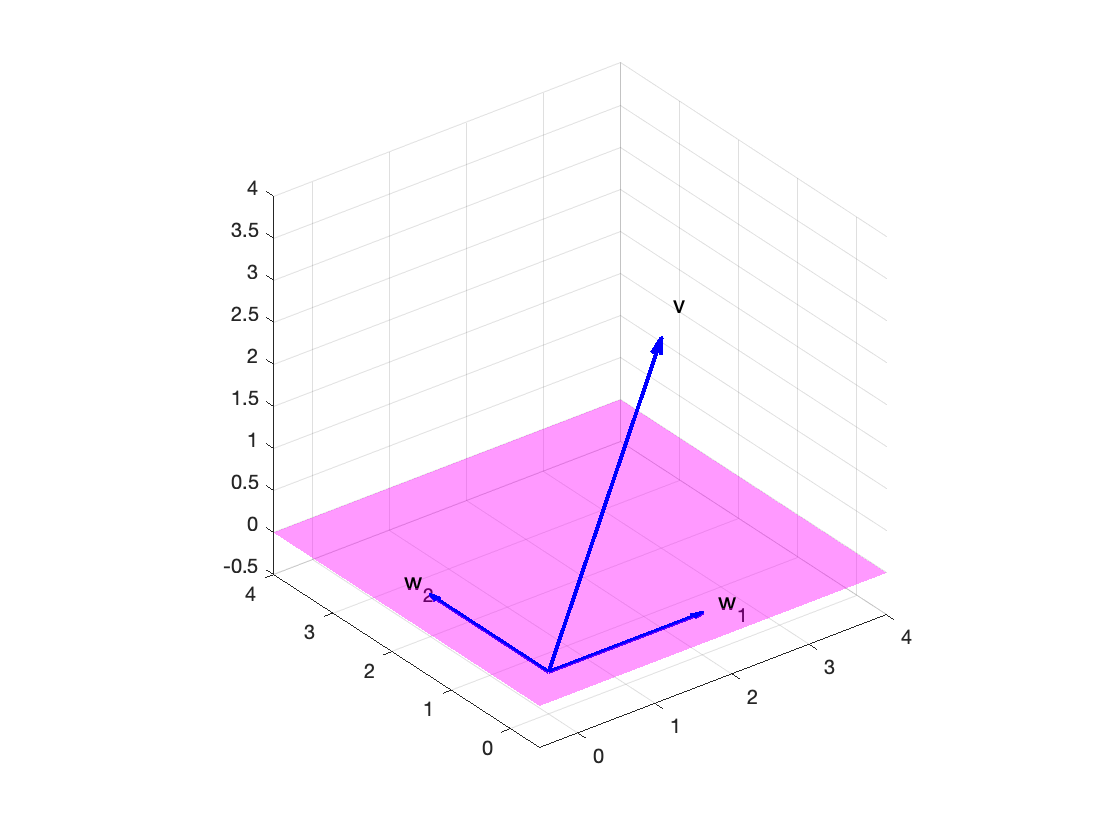

figure
hold on
s=linspace(-4,4,20);
t=linspace(-4,4,20);
[S,T]=meshgrid(s,t);
X=2*S;
Y=2*T;
Z=zeros(size(T));
surf(X,Y,Z,'FaceColor','m','FaceAlpha',0.4,'EdgeColor','none')
quiver3(0,0,0,2,0,0,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,0,2,0,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,3,2,2,0,'LineWidth',2,'Color','b')
axis equal
axis([-0.5,4,-0.5,4,-0.5,4])
grid on
text(2.2,0,0,'w_1','FontSize',12)
text(0,2.2,0,'w_2','FontSize',12,'HorizontalAlignment','center')
text(3.3,2.2,2.2,'v','FontSize',12)
view(3)

Strong visual evidence that $B_W=\{\textbf w_1,\ \textbf w_2\}$ is an orthogonal basis. We can rotate the image if we are not sure that $\textbf w_1$ and $\textbf w_2$ are orthgonal. Now, let's try the orthogonal projection formula again, and see if it works this time. Let's first compute the projections of the vector $\textbf v$ onto the vectors $\textbf w_1$ and $\textbf w_2$.

$\begin{array}{rcl}
\textbf{proj}_{\textbf w_1}\textbf v&=&\frac{\textbf v\cdot\textbf w_1}{\textbf w_1\cdot\textbf w_1}\textbf w_1\\
&=&\frac{(3,2,2)\cdot(2,0,0)}{2,0,0)\cdot(2,0,0)}\pmatrix{2\cr 0\cr 0}\\
&=&\frac{6}{4}\pmatrix{2\cr 0\cr 0}\\
&=&\pmatrix{3\cr 0\cr 0}
\end{array}$          and          $\begin{array}{rcl}
\textbf{proj}_{\textbf w_2}\textbf v&=&\frac{\textbf v\cdot\textbf w_2}{\textbf w_2\cdot\textbf w_2}\textbf w_2\\
&=&\frac{(3,2,2)\cdot(0,2,0)}{(0,2,0)\cdot(0,2,0)}\pmatrix{0\cr 2\cr 0}\\
&=&\frac{4}{4}\pmatrix{0\cr 2\cr 0}\\
&=&\pmatrix{0\cr 2\cr 0}
\end{array}$

We can check these with Matlab.

p1=dot(v,w1)/dot(w1,w1)*w1

p1 =      3
     0
     0


p2=dot(v,w2)/dot(w2,w2)*w2

p2 =      0
     2
     0


Same as our hand-calculated answers. Now, let's add these projection vectors to our image.

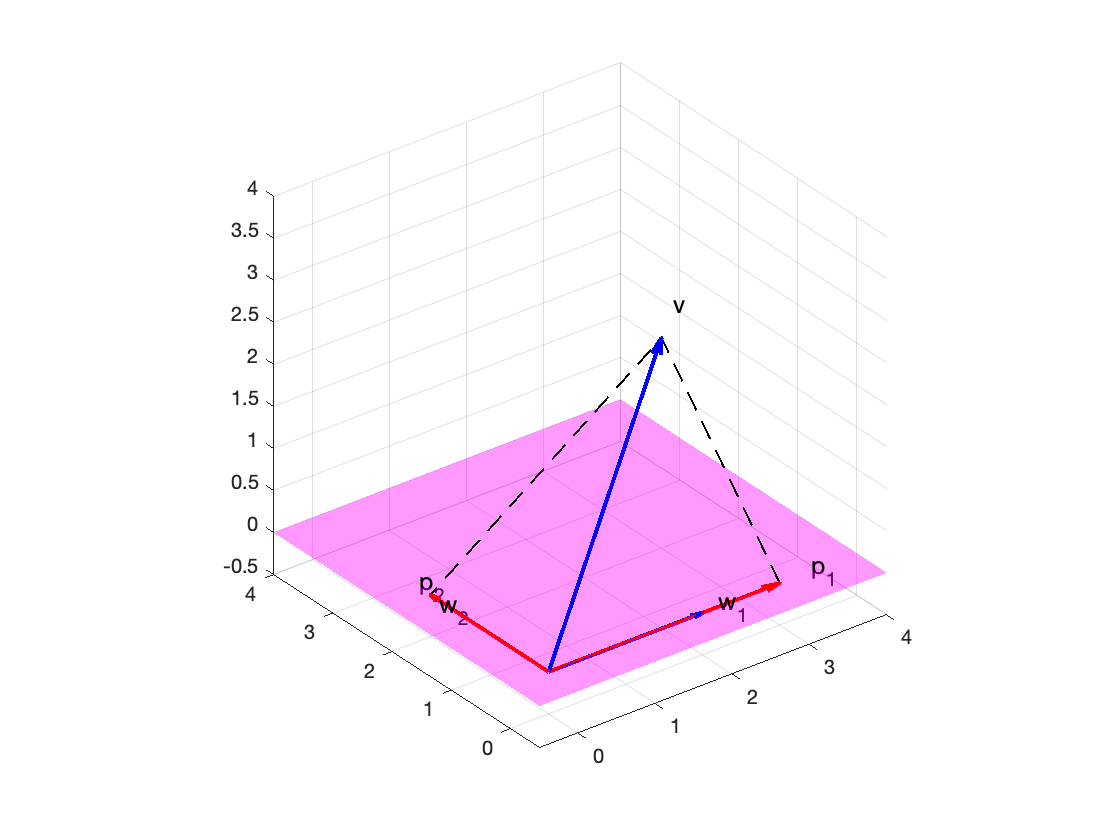

figure
hold on
s=linspace(-4,4,20);
t=linspace(-4,4,20);
[S,T]=meshgrid(s,t);
X=2*S;
Y=2*T;
Z=zeros(size(T));
surf(X,Y,Z,'FaceColor','m','FaceAlpha',0.4,'EdgeColor','none')
quiver3(0,0,0,2,0,0,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,0,2,0,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,3,2,2,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,3,0,0,0,'LineWidth',2,'Color','r')
quiver3(0,0,0,0,2,0,0,'LineWidth',2,'Color','r')
line([3,3,0],[0,2,2],[0,2,0],'LineWidth',1,'LineStyle','--','Color','k')
axis equal
axis([-0.5,4,-0.5,4,-0.5,4])
grid on
text(2.2,0,0,'w_1','FontSize',12)
text(0,1.6,0,'w_2','FontSize',12,'HorizontalAlignment','center')
text(3.3,2.2,2.2,'v','FontSize',12)
text(3.4,0,0,'p_1','FontSize',12)
text(0,2.2,0,'p_2','FontSize',12)
view(3)

Next,


$$\textbf w=\text{proj}_{\textbf w_1}\textbf v+\text{proj}_{\textbf w_2}\textbf v=\pmatrix{3\cr 0\cr 0}+\pmatrix{0\cr 2\cr 0}=\pmatrix{3\cr 2\cr 0}$$


We can check this with Matlab.

w=p1+p2

w =      3
     2
     0


Next,


$$\textbf u=\textbf v-\textbf w=\pmatrix{3\cr 2\cr 2}-\pmatrix{3\cr2\cr0}=\pmatrix{0\cr0\cr 2}$$


And we can check this with Matlab.

u=v-w

u =      0
     0
     2


Now, let's add these vectors to our image.

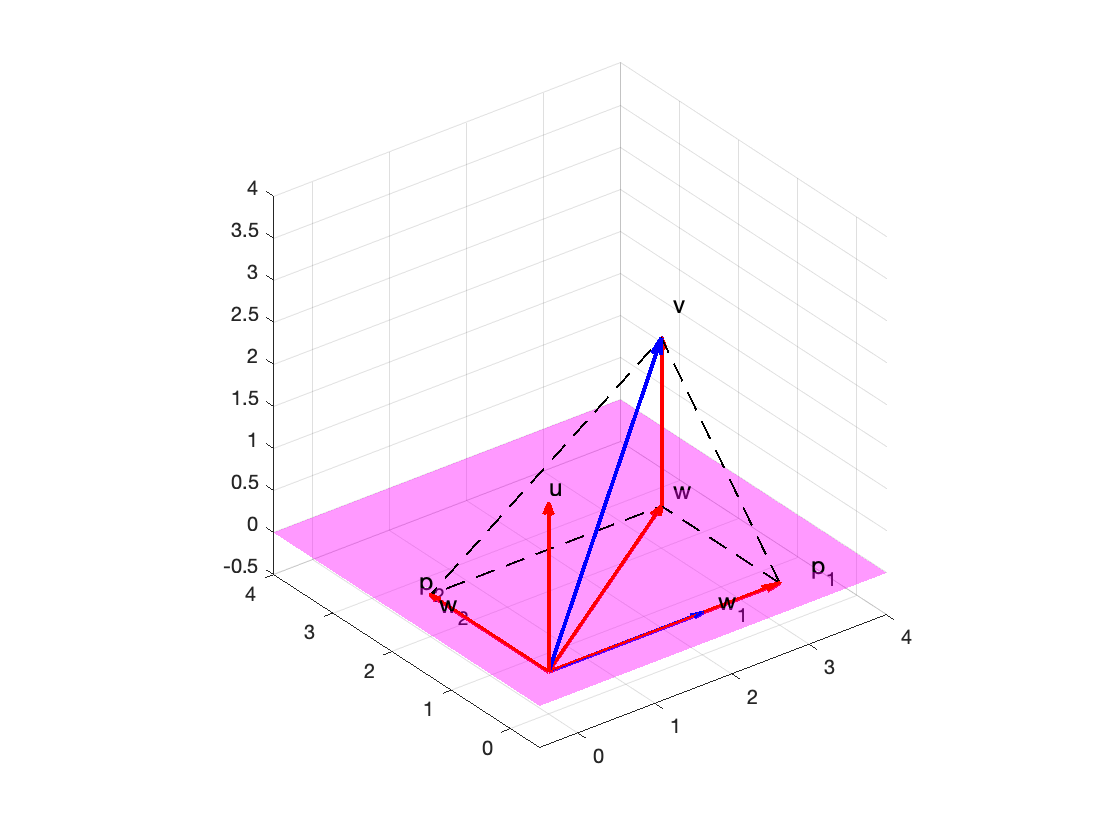

figure
hold on
s=linspace(-4,4,20);
t=linspace(-4,4,20);
[S,T]=meshgrid(s,t);
X=2*S;
Y=2*T;
Z=zeros(size(T));
surf(X,Y,Z,'FaceColor','m','FaceAlpha',0.4,'EdgeColor','none')
quiver3(0,0,0,2,0,0,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,0,2,0,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,3,2,2,0,'LineWidth',2,'Color','b')
quiver3(0,0,0,3,0,0,0,'LineWidth',2,'Color','r')
quiver3(0,0,0,0,2,0,0,'LineWidth',2,'Color','r')
quiver3(0,0,0,3,2,0,0,'LineWidth',2,'Color','r')
quiver3(0,0,0,0,0,2,0,'LineWidth',2,'Color','r')
quiver3(3,2,0,0,0,2,0,'LineWidth',2,'Color','r')
line([3,3,0],[0,2,2],[0,2,0],'LineWidth',1,'LineStyle','--','Color','k')
line([3,3,0],[0,2,2],[0,0,0],'LineWidth',1,'LineStyle','--','Color','k')
axis equal
axis([-0.5,4,-0.5,4,-0.5,4])
grid on
text(2.2,0,0,'w_1','FontSize',12)
text(0,1.6,0,'w_2','FontSize',12,'HorizontalAlignment','center')
text(3.3,2.2,2.2,'v','FontSize',12)
text(3.4,0,0,'p_1','FontSize',12)
text(0,2.2,0,'p_2','FontSize',12)
text(0,0,2.2,'u','FontSize',12)
text(3.3,2.2,0,'w','FontSize',12)
view(3)

This is clear visual evidence that $\textbf u$ is orthogonal to $W=\text{span}\{\textbf w_1,\ \textbf w_2\}$, but we can also check this with Matlab. 

dot(u,w1)

ans = 0

dot(u,w2)

ans = 0

Therefore, $\textbf u$ is orthogonal to each vector in the basis $B_W=\{\textbf w_1,\ \textbf w_2\}$, so it is orthogonal to every vector in the plane.